# Converting a RasCAL1Project to RAT format. 

If you have a number of old rascal projects that you would like to load into RAT, it's not necessary to re-make the project from scratch. Rather, you can simply run the converstion utility supplied with the RAT repo to translate the project directly.

The project we are going to use for demonstrations comes from the RasCAL_2019 distro, and is an alaysis of a monolayer of DSPC analysed at multiple contrasts. We use various deuterations of DSPC, so either tail-deuterated, head deuterated, fully deuterated or hydrogenated....

                                                                                        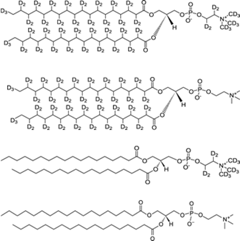

..and these are measured either on D2O or ACMW, to give 7 contrasts in all.

The original R1 project is in 'monolayerVolumeModel.mat'. The custom model is 'Model_IIb.m'. To do the conversion, we simply run the utility....

problem = r1ToProjectClass('monolayerVolumeModel.mat')
problem.setCustomFile(1,'path', 'examples/miscellaneous/convertRascal1Project');

...and that's it! We have a full RAT projectClass with all the relevant parameters in the correct place.

To run this, we make a controls.block as ususal, send it to RAT and see what we end up with...

controls = controlsClass();
[problem,results] = RAT(problem,controls);

% Plot this out
figure; clf; hold on
plotRefSLD(problem,results);

Looking at the project, we see a couple of things that we might like to change...

- The bulk out parameters are not being fit, we would like to fit these, so change the fit values of these to 'true'..

- The same goes for the scalefactor

- We would like to do a Bayesian analysis, so set the priors to be visible..

- Set some priors on the 'bulk out' parameters

We do this by modifying our projectClass with the class methods as usual....

problem.setBulkOut(1,'fit',true);
problem.setBulkOut(2,'fit',true);
problem.setScalefactor(1,'fit',true);

problem.showPriors = true;
problem.bulkOut.setPrior(1,'gaussian',6.35e-6,1e-8);
problem.bulkOut.setPrior(2,'gaussian',0,1e-7);
disp(problem)

## Running a full analysis..

We will, as usual, run a Bayesian analysis using DREAM.

Set our controls block to parallelise over contrasts, and select the Bayes sampler....

controls.parallel = 'contrasts';
controls.procedure = 'dream'

..and run the fit (using the defaults).

[problem,results] = RAT(problem,controls);

Plot everything out and we're done.....

figure(30); clf;
bayesShadedPlot(problem, results,'KeepAxes',true,'interval',95,'q4',false);
h3 = figure(40); clf
plotHists(results,h3,'smooth',true);
h4 = figure(5); clf
cornerPlot(results,h4,'smooth',false)